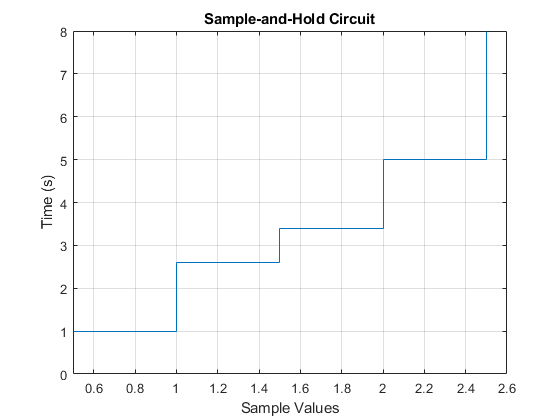

% Assignment 5
% Juan Silva
% ECE 309
% Feb. 21, 2018

% 1.Generate a plot for the signal that is the output of 
% a sample-and-hold circuit, if the samples values: 
% {1,  2.6,  3.4,  5,  8} were taken at fs = ½ sample/sec., 
% starting at t = 0 sec.

fs = [0.5:0.5:2.5];
values = [1 2.6 3.4 5 8];

stairs(fs,values)
axis([0.5 2.6 0 8])
grid
title('Sample-and-Hold Circuit')
xlabel('Sample Values')
ylabel('Time (s)')

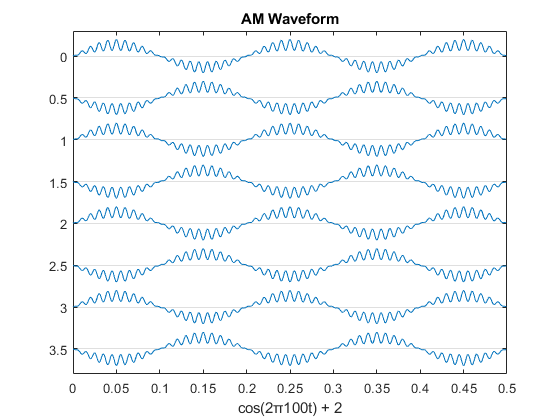


% 2. Use a strip plot to generate 4 seconds worth of data (starting 
% at t = 0), where each “strip” is .5 seconds worth of data, for 
% the AM signal:s(t) { cos(2p100t) + 2}

fs = 1000;          %sample
ts = 1/fs;          %time value
t = [0:ts:4];       %4 seconds of time values

message = sin(10*pi*t);                            %message frequency
signalFreq = message .* (cos(2*pi*100*t) + 2);     %signal frequency
strips(signalFreq, .5, fs);                        %plot strip

title('AM Waveform')
xlabel('cos(2π100t) + 2')

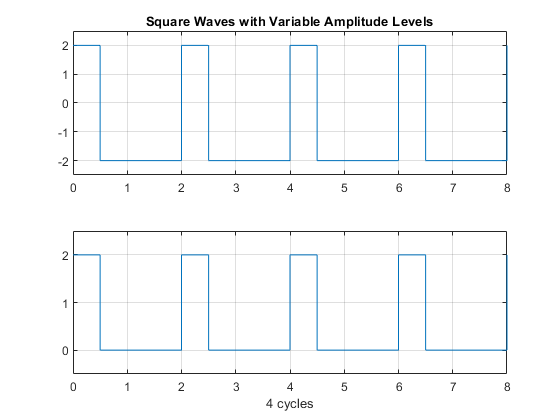


% 3a. Plot 4 cycles of the square wave with amplitude levels {+2, -2}, 
% period T = 2 sec., and duty cycle 25% (for the “high” value).  
% (Choose a reasonable value for fs.)

fs = 1000;    % sample
ts = 1/fs;    % sampe time

T = 2;        % two seconds
f = 1/T;      % frequency
amp = 2;      % amplitude 
t = 0:ts:8;   % time in seconds (4 cycles * 2 seconds)
D = 25;       % duty percent

subplot(2,1,1)
sqw = amp .* square(2*pi.*f.*t, D);
plot(t,sqw);
ylim([-2.5 2.5])
grid
title('Square Waves with Variable Amplitude Levels')

% 3b. Repeat problem 3a, but change the amplitude levels to {0, 2}.
subplot(2,1,2)
sqw2 = (sqw + 2) / 2;
plot(t,sqw2);
ylim([-0.5 2.5])
grid
xlabel('4 cycles')

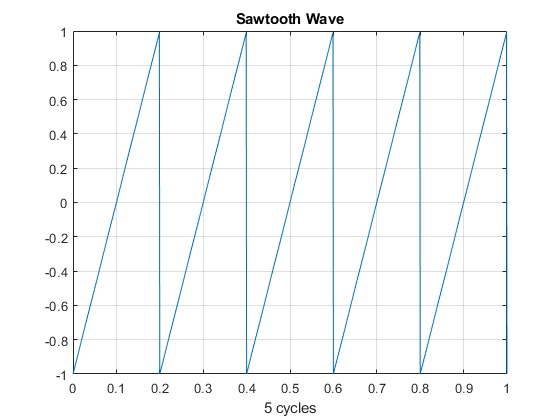

figure


% 4.Plot 5 cycles of a triangular (sawtooth) wave, where the peak is 
% at the end of the cycle, and the period is T = .2 sec. 
% (Choose a reasonable value for fs.)

fs = 1000;
ts = 1/fs;

T = 0.2;
f = 1/T;            
t = 0:ts:1;
k = 1;        %default value

saw = sawtooth(2*pi*f.*t, k);
plot(t,saw);
grid
title('Sawtooth Wave')
xlabel('5 cycles')

figure


% 5.Use MATLAB’s repmat function to plot a discrete sequence 
% with 6 repetitions of: {0, 1, 2, 3, 4}, starting at n = 0.
A = [0:4]

A =      0     1     2     3     4


B = repmat(A,1,6)

B =      0     1     2     3     4     0     1     2     3     4     0     1     2     3     4     0     1     2     3     4     0     1     2     3     4     0     1     2     3     4


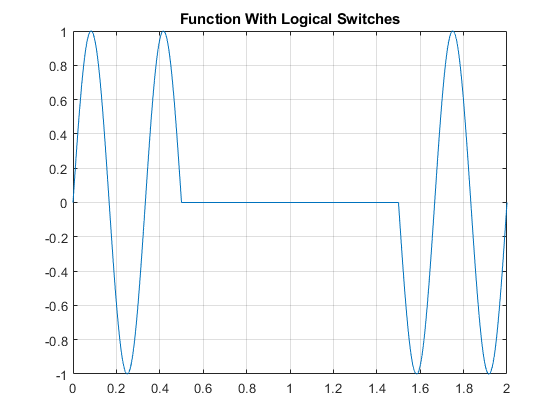


% 6.Use logical switches to plot the function shown:
fs = 8192;
ts = 1/fs;
t = 0:ts:2;

sw1 = (t < 0.5);
sw2 = (t >= 0.5) & (t < 1.5);
sw3 = (t >= 1.5);

x = sw1 .* sin(6*pi.*t) + sw2 * 0 + sw3 .* sin(6*pi.*t);

plot(t,x)
grid
title('Function With Logical Switches')


% 7 Consider the matrix pascal(6).  Make a 2-column table showing the row and 
% column for all entries in this matrix that are greater than 50. Hint: 
% Type:  >> help pascal, and >> help find.

A = pascal(6)

A =      1     1     1     1     1     1
     1     2     3     4     5     6
     1     3     6    10    15    21
     1     4    10    20    35    56
     1     5    15    35    70   126
     1     6    21    56   126   252



[row, column] = find(A > 50);

display('   row      column')

   row      column


display([row, column])

     6     4
     5     5
     6     5
     4     6
     5     6
     6     6



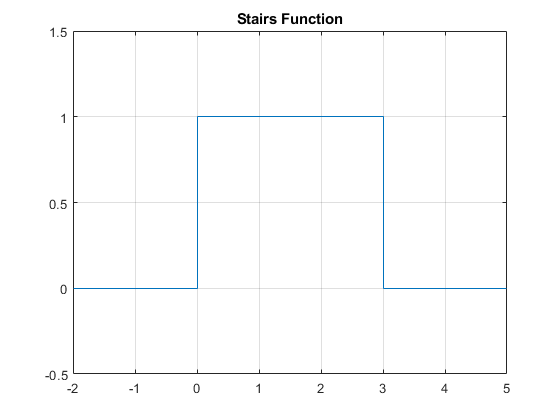


% 8.Use MATLAB’s stairs function to generate the plot below. (If you have had ECE 350, 
% you may recognize this as the window:          u(t) –u(t –3).) Use the same scales 
% for the axes as shown.

t = [-2:5];
values = [0 0 1 1 1 0 0 0];

stairs(t,values)
axis([-2 5 -0.5 1.5])
grid
title('Stairs Function')

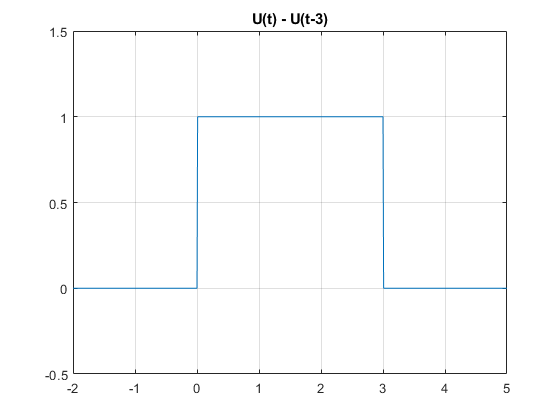

figure

% 8b. Create an array 'U' implementing the expression u(t)-u(t-3). Use 
% Comparison switches (<, >, etc.) as it was demonstrated in the classroom.
t = [-2:0.01:5];
sw2 = (t > 0) - (t - 3 > 0);

plot(t, sw2)
axis([-2 5 -0.5 1.5])
grid
title('U(t) - U(t-3)')